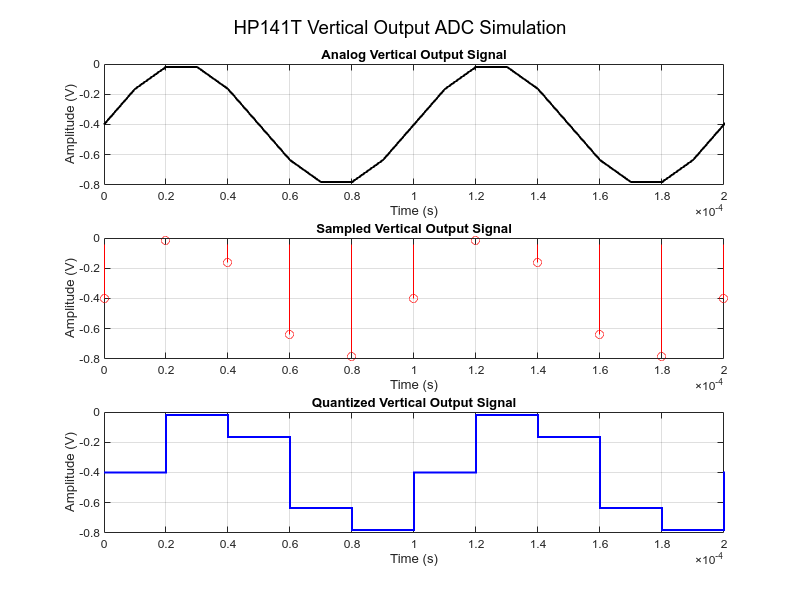

% High-speed ADC simulation for HP141T Spectrum Analyzer
% Simulates digitization of the vertical output signal (Vy: -0.8V to 0V)
% from HP8555A RF section and HP8552B IF section with a 10 kHz calibration signal.

% Step 1: Define the vertical output analog signal (Vy)
f = 10000;              % Signal frequency (Hz)
A = 0.4;                % Amplitude (V, for -0.8V to 0V peak-to-peak)
B = -0.4;               % DC offset (V)
Fs = 100000;            % Signal generation sampling frequency (Hz, oversampled for accuracy)
T = 1/Fs;               % Signal sampling period (s)
L = 1000;               % Number of samples
t = (0:L-1)*T;          % Time vector (s)
Vy = A*sin(2*pi*f*t) + B; % Vertical output sine wave (V)

% Step 2: Characterize the ADC
res = 16;               % ADC resolution (bits)
Vref = 1.0;             % ADC reference voltage (V, bipolar: -Vref to +Vref)
Fs_adc = 50000;         % ADC sampling frequency (Hz, >2*f for Nyquist)
T_adc = 1/Fs_adc;       % ADC sampling period (s)
qLevels = 2^res;        % Number of quantization levels
qStep = (2*Vref)/(qLevels-1); % Quantization step size (V)

% Step 3: Sample the vertical output signal
numSamples = 0:T_adc:max(t); % ADC sampling time points
sampledSig = A*sin(2*pi*f*numSamples) + B; % Sampled signal

% Step 4: Quantize the sampled signal
% Clip signal to ADC input range [-Vref, Vref]
sampledSig = max(min(sampledSig, Vref), -Vref);
qSig = round((sampledSig + Vref) / qStep) * qStep - Vref; % Quantized signal

% Step 5: Encode quantized signal to binary (two's complement)
digitalSig = zeros(length(qSig), res); % Binary matrix
for i = 1:length(qSig)
    % Convert to integer code (0 to 2^res-1) and then to binary
    code = round((qSig(i) + Vref) / qStep);
    digitalSig(i, :) = bitget(code, 1:res);
end

% Step 6: Plot analog, sampled, and quantized signals
figure;
% Analog signal
subplot(3,1,1);
plot(t, Vy, 'k', 'LineWidth', 1.5);
title('Analog Vertical Output Signal');
xlabel('Time (s)'); ylabel('Amplitude (V)');
grid on; xlim([0, 2/f]); % Show two periods

% Sampled signal
subplot(3,1,2);
stem(numSamples, sampledSig, 'r', 'Marker', 'o');
title('Sampled Vertical Output Signal');
xlabel('Time (s)'); ylabel('Amplitude (V)');
grid on; xlim([0, 2/f]);

% Quantized signal
subplot(3,1,3);
stairs(numSamples, qSig, 'b', 'LineWidth', 1.5);
title('Quantized Vertical Output Signal');
xlabel('Time (s)'); ylabel('Amplitude (V)');
grid on; xlim([0, 2/f]);

% Adjust figure properties
sgtitle('HP141T Vertical Output ADC Simulation');
set(gcf, 'Position', [100, 100, 800, 600]);